# Running a Gear

Flywheel uses the term 'Gear' to describe the process of

   * retrieving data from a scitran database,

   * selecting the parameters,

   * analyzing the data with a program stored in a docker container, and

   * placing the result and parameters into the database for

     scientific transparency and reproducibility

This script illustrates one simple Gear for anatomical processing (skull-stripping). In this example, we execute a docker container built to run the FSL brain extraction tool (bet2). Data are retrieved from a scitran database and processed. The result are placed back in the scitran database.

There will be many other gears for a very wide range of data processing purposes. We are building gears for (a) tractography, (b) cortical mesh visualization, (c) quality assurance, (d) tissue measurement, (e) spectroscopy, and ...

Operating Gears is possible from within the web browser via an easy-to-use graphic interface (pulldown menus and forms to set the parameters).

This code shows the principles of what happens behind the graphical user interface in the browser window.

This script illustrates how to interact from the command line with the scitran database using Matlab. There is also a Python interface. Using these command line tools, you can build your own Gears.

We are committed to making our code and parameters transparent, and we are committed to helping you create and share your own Gears. That's why we call this the project on scientific transparency!

LMP/BW, Scitran Team, 2016

## Authorization

% Get authorization to read from the database
st = scitran('scitran');

% A place for temporary files.
chdir(fullfile(stRootPath,'local'));

## Configure your local computer to run docker containers

% A docker container is a virtual machine that can be copied to almost any
% computer and run there.  We can have many different docker containers
% that execute all kinds of data processing

% Docker containers can run either locally, on your machine, or on a remote
% computer in the Cloud.  In this example, we will run the brain extraction
% tool from FSL, which we have installed in a docker container.  The first
% time you run this code it can take a little while to install the docker
% system.
stDockerConfig('machine', 'default');

% Make an empty directory for the input to the docker container
iDir    = fullfile(pwd,'input');
stDirCreate(iDir);


% Make an empty directory for the output from the docker container
oDir = fullfile(pwd,'output');
stDirCreate(oDir);

## Execute a simple search

% This search could also be done from the browser interface

% We are searching for T1 weighted files in the GearTest collection.
[files, srchS] = st.search('files',...
    'acquisition label contains','T1w',...
    'filetype','nifti',...
    'file name','11348_3_1.nii.gz',...
    'collection label','GearTest');

## Get the file from the scitran database

% Execute the docker container on one file.  This could be a loop.
fname = files{1}.source.name;
destFile = fullfile(iDir, fname);

% Get the file from the database
st.get(files{1},'destination',destFile);

## Set up for the brain extraction tool docker container and run it

% Build the docker structure to run the container
clear docker
docker.iDir  = iDir;
docker.oDir  = oDir;

% The input file
docker.iFile =  fname;

% For this particular FSL tool (brain extraction) do this.
baseName = strsplit(docker.iFile,'.nii.gz');
docker.oFile  = [baseName{1},'_bet'];

% Indicate that we want to run the brain extraction tool (bet) docker
% container
docker.container = 'vistalab/bet';

% The docker struct and the files cell array contains the information
% needed for reproducibility
st.docker(docker);

Running bet2...
Wrote: 11348_3_1_bet.nii.gz
vistalab/bet returned successfully


## Visualize the file

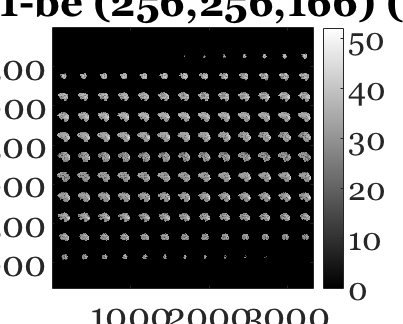


betFile = fullfile(docker.oDir,[docker.oFile,'.nii.gz']);
niftiView(betFile);

## Build analysis struct with the information needed to upload the results

% NOTE: Full paths are required for the outputs and inputs.
clear upload
analysis.label           = [datestr(datetime('now')), ' s_stGear: FSL bet2 analysis'];        % Analysis label
analysis.outputs{1}.name = fullfile(docker.oDir, [docker.oFile,'.nii.gz']); % Full path to the OUTPUT file
analysis.inputs{1}.name  = fullfile(docker.iDir, docker.iFile);             % Full path to the INPUT file
analysis.user = 'LM Perry and B Wandell';

## UPLOAD ANALYSIS TO COLLECTION

## `This makes the analysis visisble from any session within that collection.`

% Find the database ID for the Collection so we can upload to it
collections = st.search('collections',...
    'collection label','GearTest');
collection_id  = collections{1}.id;

st.put('collection analysis', analysis,'id', collection_id);

% Go to the browser and have a look at the collection
st.browser('','collection',collections{1});

## UPLOAD ANALYSIS TO THE SESSION

% Get the SESSION ID which contains the acquisitions and the file we used
% for input (this ID is needed for a session analysis)

session = st.search('sessions',...
    'session label',files{1}.source.session.label,...
    'collection label','GearTest');    
session_id                  = session{1}.id;

st.put('session analysis', analysis, 'id', session_id);


## Browse the session


st.browser(session{1},'tab','analysis');